# Longitudinal Vehicle

## Coastdown

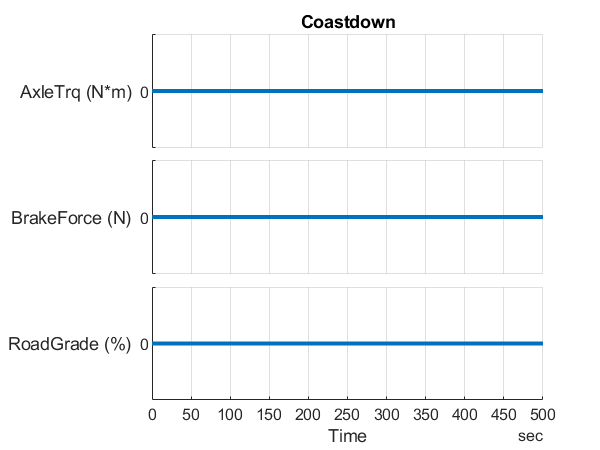

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

Vehicle1D_harness_setup

vehSigBuilder = Vehicle1D_InputSignalBuilder("Plot_tf",true);

inpData = Coastdown(vehSigBuilder, ...
            "StopTime", seconds(500), ...
            "InitialVehicleSpeed_kph", 100, ...
            "AxleTorque_Const_Nm", 0, ...
            "BrakeForce_Const_N", 0, ...
            "RoadGrade_Const_pct", 0 );

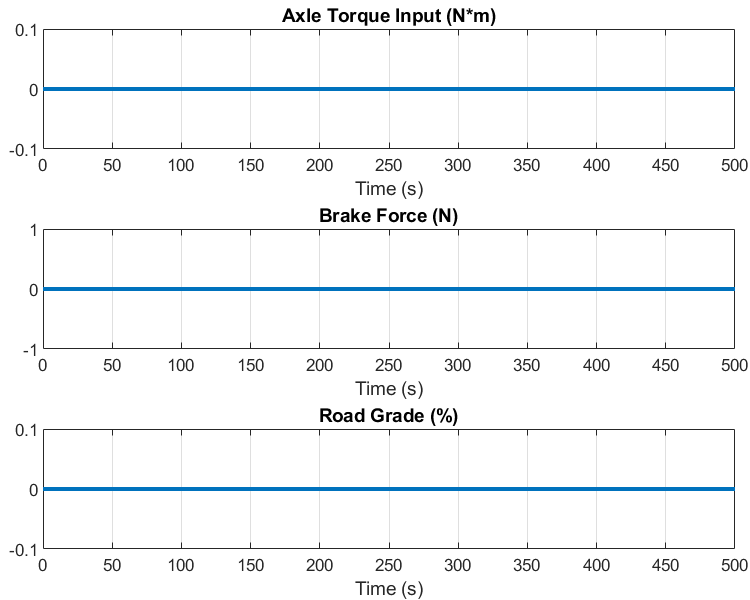

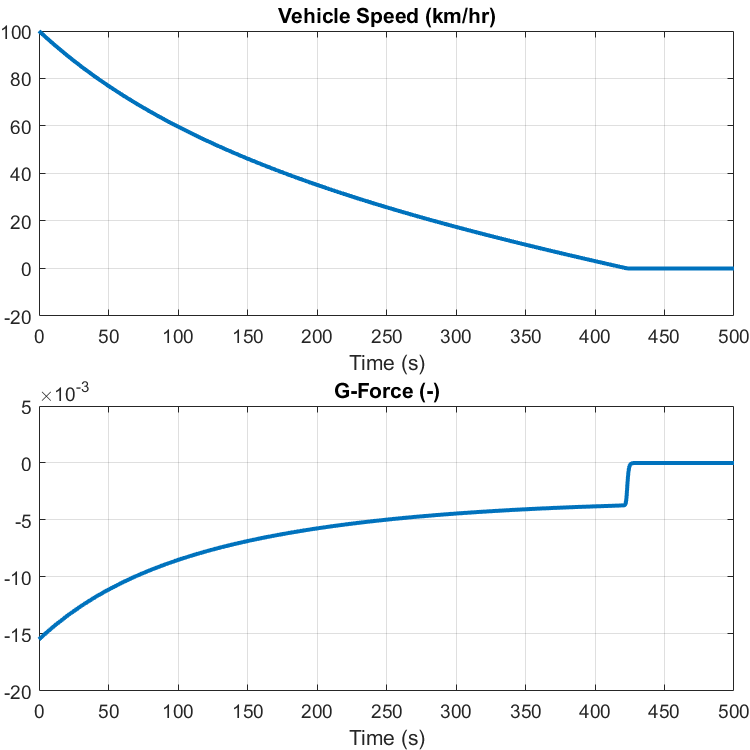

simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn, "vehicle_InputSignals", inpData.Signals);
simIn = setVariable(simIn, "vehicle_InputBus", inpData.Bus);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));

% In R2021a, use setVariable.
simIn = setVariable(simIn, "initial.vehicleSpeed_kph", ...
          inpData.Options.Coastdown.InitialVehicleSpeed_kph);

% simIn = setBlockParameter(simIn, ...
%   mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x", "100", ...
%   mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x_unit", "km*hr", ...
%   mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x_priority", "high");

simOut = sim(simIn);

Vehicle1D_plot_results(simOut.logsout);

*Copyright 2020-2022 The Mathworks, Inc.*